% Potential_OCP(P),Temperature(T),K_concentration(K)
% K_Sensors.xlsx
% 1st row (Potential/P);
% 2nd row (Temperature/Cel.);
% 3rd row (K cencentration/mol·L-1)；
% global P T K P_hight T_hight K_hight

DataInput = xlsread('K_Sensors.xlsx');
% DataInput_mesh = xlsread('K_Sensors_mesh.xlsx');

P = DataInput(:,3);
P_hight = height(P);
[Pn,Ps] = mapminmax(P',0.1,0.9) % normalized

Pn =     0.1000    0.1001    0.1003    0.1005    0.1006    0.1008    0.1010    0.1011    0.1013    0.1014    0.1016    0.1017    0.1019    0.1021    0.1022    0.1024    0.1026    0.1027    0.1029    0.1031    0.1032    0.1034    0.1035    0.1037    0.1038    0.1040    0.1042    0.1043    0.1045    0.1047    0.1048    0.1050    0.1052    0.1053    0.1055    0.1056    0.1058    0.1059    0.1061    0.1063    0.1064    0.1066    0.1068    0.1069    0.1071    0.1073    0.1074    0.1076    0.1077    0.1079


Ps = struct with fields:
         name: 'mapminmax'
        xrows: 1
         xmax: 0.0092
         xmin: -0.2156
       xrange: 0.2249
        yrows: 1
         ymax: 0.9000
         ymin: 0.1000
       yrange: 0.8000
         gain: 3.5575
      xoffset: -0.2156
    no_change: 0



T = DataInput(:,2);
T_hight = height(T);
[Tn,Ts] = mapminmax(T',0.1,0.9) % normalized

Tn =     0.1000    0.1008    0.1016    0.1024    0.1032    0.1040    0.1048    0.1056    0.1064    0.1072    0.1080    0.1088    0.1096    0.1104    0.1112    0.1120    0.1128    0.1136    0.1144    0.1152    0.1160    0.1168    0.1176    0.1184    0.1192    0.1200    0.1208    0.1216    0.1224    0.1232    0.1240    0.1248    0.1256    0.1264    0.1272    0.1280    0.1288    0.1296    0.1304    0.1312    0.1320    0.1328    0.1336    0.1344    0.1352    0.1360    0.1368    0.1376    0.1384    0.1392


Ts = struct with fields:
         name: 'mapminmax'
        xrows: 1
         xmax: 90
         xmin: 25
       xrange: 65
        yrows: 1
         ymax: 0.9000
         ymin: 0.1000
       yrange: 0.8000
         gain: 0.0123
      xoffset: 25
    no_change: 0



K = DataInput(:,1);
K_hight = height(K);
[Kn,Ks] = mapminmax(K',0.1,0.9) % normalized

Kn =     0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000    0.9000


Ks = struct with fields:
         name: 'mapminmax'
        xrows: 1
         xmax: 4
         xmin: 0
       xrange: 4
        yrows: 1
         ymax: 0.9000
         ymin: 0.1000
       yrange: 0.8000
         gain: 0.2000
      xoffset: 0
    no_change: 0



% GRNN Simulation
% desired_spread = [];
% spread = 0.1;
% GRNNnet = newgrnn([Pn; Tn]', Kn', spread);

% BPNN Simulation
BPnet = newff([Pn;Tn],Kn,[6,8,6],{'tansig','purelin'},'trainlm');
[BPnet,tr,net_K] = train(BPnet,[Pn;Tn],Kn);

% % % % % Chose Random Experiment Data for NN
Exp_P = -0.0012 % P(randi(P_hight)) % @ Experimental value of potential (V)

Exp_P = -0.0012

Exp_Pn = mapminmax('apply', Exp_P, Ps); % normalize
Exp_T = 30 % T(randi(T_hight)) % @ Experimental value of temperature (Celsius)

Exp_T = 30

Exp_Tn = mapminmax('apply', Exp_T, Ts); % normalize

% BPNN Forcasting
Exp_Kn_bpnn = sim(BPnet,[Exp_Pn,Exp_Tn]'); % predicted K concentration Point
Exp_K_bpnn = mapminmax('reverse', Exp_Kn_bpnn, Ks) % REVerse normalized

Exp_K_bpnn = -0.4260

Real_Exp_K_bpnn = exp(-1*Exp_K_bpnn)

Real_Exp_K_bpnn = 1.5311

% GRNN Forcasting
% Exp_Kn_grnn = sim(GRNNnet,[Exp_Pn;Exp_Tn]);
% Exp_K_grnn = mapminmax('reverse', Exp_Kn_grnn, Ks); % REVerse normalized
% Exp_K_grnn = exp(Exp_K_grnn)

% BPNN mesh Forcasting
% MESH P and T
P_Mesh = -0.220:0.00235:0.015;
[P_Mesh_n,P_Mesh_s] = mapminmax(P_Mesh,0.1,0.9) % normalized

P_Mesh_n =    -0.2500
   -0.2465
   -0.2430
   -0.2395
   -0.2360
   -0.2325
   -0.2290
   -0.2255
   -0.2220
   -0.2185
   -0.2150
   -0.2115
   -0.2080
   -0.2045
   -0.2010


P_Mesh_s = struct with fields:
         name: 'mapminmax'
        xrows: 101
         xmax: [101×1 double]
         xmin: [101×1 double]
       xrange: [101×1 double]
        yrows: 101
         ymax: 0.9000
         ymin: 0.1000
       yrange: 0.8000
         gain: [101×1 double]
      xoffset: [101×1 double]
    no_change: 1



T_Mesh = 20:0.8:100;
[T_Mesh_n,T_Mesh_s] = mapminmax(T_Mesh,0.1,0.9) % normalized

T_Mesh_n =    20.0000
   20.8000
   21.6000
   22.4000
   23.2000
   24.0000
   24.8000
   25.6000
   26.4000
   27.2000
   28.0000
   28.8000
   29.6000
   30.4000
   31.2000


T_Mesh_s = struct with fields:
         name: 'mapminmax'
        xrows: 101
         xmax: [101×1 double]
         xmin: [101×1 double]
       xrange: [101×1 double]
        yrows: 101
         ymax: 0.9000
         ymin: 0.1000
       yrange: 0.8000
         gain: [101×1 double]
      xoffset: [101×1 double]
    no_change: 1


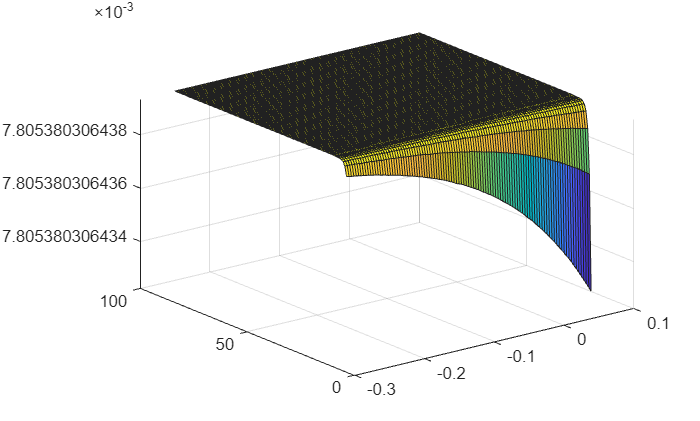


% scatter3(P_Mesh,T_Mesh,sim(BPnet,[P_Mesh;T_Mesh]))
% BPNN mesh Forcasting
 [P_Meshgrid,T_Meshgrid]=meshgrid(P_Mesh_n',T_Mesh_n');

 Exp_K_Mesh_n_bpnn=zeros(101,101);
 Exp_K_Mesh_bpnn=zeros(101,101);
 Real_Exp_K_Mesh_bpnn=zeros(101,101);
 for i=1:1:101
     for j=1:1:101
        Exp_K_Mesh_n_bpnn(i,j) = sim(BPnet,[P_Meshgrid(i,j),T_Meshgrid(i,j)]');
        Exp_K_Mesh_bpnn(i,j) = mapminmax('reverse', Exp_K_Mesh_n_bpnn(i,j), Ks); % REVerse normalized
        Real_Exp_K_Mesh_bpnn(i,j) = exp(-1*Exp_K_Mesh_bpnn(i,j));
     end
 end
 
 P_Meshgrid_n = mapminmax('reverse', P_Meshgrid, P_Mesh_s);
 T_Meshgrid_n = mapminmax('reverse', T_Meshgrid, T_Mesh_s);

 surf(P_Meshgrid_n,T_Meshgrid_n,Real_Exp_K_Mesh_bpnn);
